**Clear Functions**

clear;
close all;
clc;

**Initial Conditions**

rE = 6378; % Radius of Earth (km)
mu = 3.986e5; %mu for Earth
jTwo = 1.08263e-3; %J2 for Earth

% Inital position and velocity vectors

r0 = [20200,0,0];
v0 = [0,0,sqrt(mu/norm(r0))];


**Calculating Orbital Elements**

r = norm(r0); % Calc distance
v = norm(v0); % Calc speed
vR = (r0(1)*v0(1) + r0(2)*v0(2) + r0(3)*v0(3))/r; %Radial velocity
hV = cross(r0,v0); % Vector specific angular momentum
h = norm(hV); % Magnitude of specific angular momentum

i = acosd(hV(3)/h); % Inclination
% Node line
K = [0,0,1];
NV = cross(K,hV); % Node line vector
N = norm(NV); % Magnitude of node line


omegaRA = acosd(NV(1)/N); % Right Ascension (RA) of ascending node

if NV(2) < 0
    omegaRA = 360-omegaRA;
end


% Calculate eccentricity vector
eV = 1/mu*((v^2-mu/r)*r0-r*vR*v0);
e = norm(eV); % Magnitude of eccentricity vector

omega = acosd(dot(NV,eV)/(N*e)); % Argument of perigee

theta = acosd(dot(eV,r0)/(e*r)); % True Anomaly

rp = (h^2/mu)*(1/(1+e*cosd(0))); % Perigee radii
ra = (h^2/mu)*(1/(1+e*cosd(180))); % apogee radii


a = 1/2*(rp+ra); % Semimajor axis (km)
T = (2*pi)*sqrt(a^3/mu);

**State Vector and Timespans**

s0 = [r0;v0];

timeSpan = 0:3*T;

**Call ODE45 Function**

*Note going to call multiple times for multiple orbits on same ECIF frame*

Inputs:* t, s, *$\mu$

Output: $\overrightarrow{\textrm{sol}}$

[~, sol] = ode45(@(t,s)diffEq(t,s,mu), timeSpan, s0); 

**Figure Configuration**

figure;

hold on; grid on; grid minor; axis equal; rotate3d on
xlabel('X (km)')
ylabel('Y (km)')
zlabel('Z (km)')
title('Orbit with Perturbation Effect')


[X, Y, Z] = sphere(); 

**Plotting Orbit and Earth**

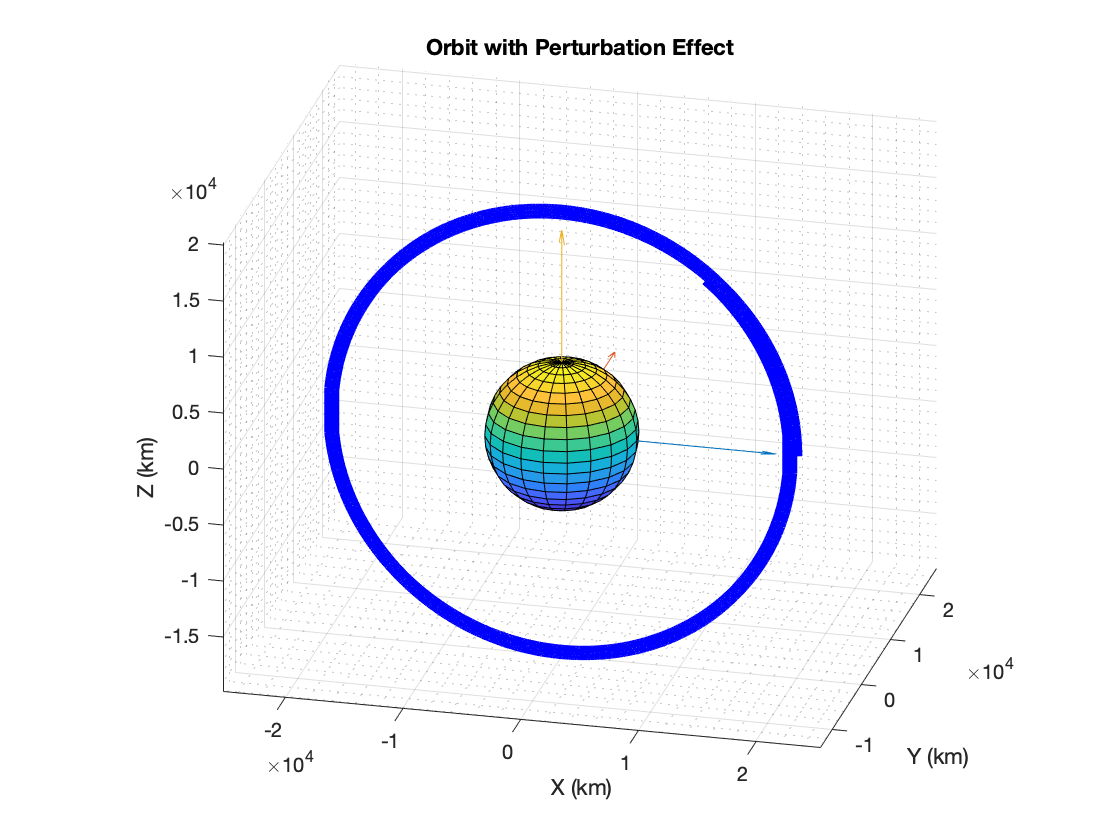

surf(X*rE, Y*rE, Z*rE);

% Draw Unit Vectors
quiver3(0,0,0,r0(1),0,0);
quiver3(0,0,0,0,r0(1),0);
quiver3(0,0,0,0,0,r0(1));

plot3(sol(:,1),sol(:,2),sol(:,3),'-b','LineWidth',3);

**Printing Outputs**

fprintf('\nGiven r = [\n%.0fI + %.0fJ +%.0fK]\n\n', r0(1), r0(2), r0(3));


Given r = [
20200I + 0J +0K]



fprintf('\nGiven v = [\n%.3fI + %.3fJ +%.3fK]\n\n', v0(1), v0(2), v0(3)); 


Given v = [
0.000I + 0.000J +4.442K]



fprintf('\nEccentrcity: %.2f', e);


Eccentrcity: 0.00

fprintf('\nPeriod = %.0f (sec)\n', T);


Period = 28572 (sec)


fprintf('\nEccentricity Vectors = [\n%.4fI + %.4fJ +%.4fK]', eV(1), eV(2), eV(3));


Eccentricity Vectors = [
0.0000I + 0.0000J +0.0000K]

fprintf('\nSemi Major Axis = %.0f (km)\n', a);


Semi Major Axis = 20200 (km)


fprintf('Right Ascension = %.3f (degrees)\n',omegaRA);

Right Ascension = 0.000 (degrees)


**ODE45 Function**

function sdot = diffEq(t,s,mu)
rE = 6378; % Radius of Earth (km)
jTwo = 1.08263e-3; %J2 for Earth


% r is first three elements, v is last three
rDQ = s(1:3);
vDQ = s(4:6);

sdot(1:3,1) = vDQ; %First three elements are velocity
sdot(4:6,1) =  -(mu*rDQ)/norm(rDQ)^3*(1-3/2*jTwo*(rE/norm(rDQ))^2*(5*(rDQ(3)^2/norm(rDQ)^2)-1)); % EOM with perturbation


end

